# Chapter 2: The Abelson's models

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 2.1 Abelson's models of opinion dynamics

Abelson proposed a continuous-time counterpart of the French-DeGroot model [M1.1](matlab:open('./ch01_fdg.mlx')). The derivation can be found inside section 4.1 in the [following paper](matlab:open('../1-s2.0-S1367578817300172-mainext.pdf')).

The continous time linear dynamics is 

                                                            (M2.1)$\dot x_i(t) = \sum _{j \ne i} a_{ij}(x_j(t)-x_i(t)), \ i = 1, \dots, n$

$A = (a_{ij})$ is a non-negative matrix of influence weights. 

A more general nonlinear  mechanism of opinion evolution is

                                                            (M2.2)$\dot x_i(t) = \sum _{j \ne i} a_{ij}g(x_i,x_j)(x_j(t)-x_i(t)), \ \forall i$

$g: \mathbb R \times \mathbb R \rightarrow (0,1]$ is a coupling function describing the complex mechanism of opinion assimilation.

We mainly deal with the **linear Abelson model** M2.1 whose equivalent matrix form is

                                                                        (M2.3)$\dot x(t) = -L[A]x(t)
$

where $L[A]$ is the Laplacian Matrix.

## 2.2 Convergence and Consensus criteria

Note that Corollary 0.X (da inserire link), applied to the M-matrix $L[A]$ and $\lambda_0=0$, implies that all Jordan blocks, corresponding to the eigenvalue $\lambda_0=0$, are trivial and for any other eigenvalue $\lambda$ of the Laplacian the real part is greater than zero. Thus M2.3 is Lyapunov stable (yet not asymptotically stable) and, unlike FDG model, is always convergent.

**Corollary 2.1** For any nonnegative matrix $A$ the limit $P^\infty = \lim_{t \rightarrow \infty} e^{-L[A]t}$ exists, and thur the vectors of opinions in M2.3 converges $x(t) \rightarrow x^\infty = P^\infty x(0)$ for $t \rightarrow \infty$.

The matrix $P^\infty$ is a projection operator onto the Laplacian's null space, $\ker L[A] = \{v : L[A]v = 0\},$and is therefore closely related to the structure of the graph. Similarly to the discrete-time model M1.1 , system M2.3 reaches consensus if, for every initial condition $x(0)$, $x_1^\infty = \cdots = x_n^\infty$. Hence, consensus requires $\mathbb{Im} P^\infty \subseteq span\{\mathbb{1}_n\},$ so that $P^\infty = \mathbb{1}_n p_\infty^\top$ for some $p_\infty \in \mathbb{R}^n$ . Since $\mathbb{1}_n$ is an equilibrium point, $P\mathbb{1}_n = \mathbb{1}_n,$and consequently $p_\infty^\top \mathbb{1}_n = 1.$Moreover, because $P$ commutes with $L[A]$, $p_\infty^\top L[A] = 0.$ Since $L[A]$ has a nonnegative left eigenvector $p$ associated with the eigenvalue $0$, and $\dim \  \ker L[A] = 1$ , it follows that $p_\infty = cp,  c>0.$ Thus, by combining these properties, one obtains the following consensus criterion.

**Theorem 2.1 **The lineare Abelson model M2.3 reaches consensu $\iff$ $\mathcal G[A]$ is quasi-strongly connected. In this case, the opinions converge to the limit $\lim_{t\rightarrow \infty}x_1(t) = \dots = \lim_{t\rightarrow \infty} x_n(t) = p_\infty^Tx(0)$ where $p^\infty \in \mathbb R$ is the nonnegative vector, uniquely defined by the equations $p_\infty^TL[A]=0$ and $p_\infty^T \mathbb 1_n = 1$.

The vector $p_\infty$ may be treated as a vector of the agent's social powers, or a centrality measure on the nodes of $\mathcal G[A]$.

Model  M2.3 arises as a "limit" of the FDG model as the time between consecutive opinion updates becomes negligibly small. The inverse operation of discretization transforms  M2.3 into the FDG model.

**Lemma 2.1 **For any nonnegative matrix $A$ and $\tau >0$ the matrix $W_\tau = e^{-\tau L[A]}$ is stochastic, and thus $P^{\infty} = \lim_{\tau \rightarrow \infty} W_\tau$ from **Corollary 2.1** is stochastic. The matrices $W_\tau$ have positive diagonal entries.

Such lemma imples that vectors $\tilde x(k) = x(\tau k)$ satisfy a special FDG model with $W = W_\tau$ and allows to derive Theorem 2.1 from Corollary 1.1.

## 2.3 The community cleavage problem

The informal formulation, stated by Abelson, was: *"Since universal ultimate agreement is an ubiquitous outcome of a very broad class of mathematical models, we are naturally led to inquire what on earth one must assue in order to generate bimodal outcome of community cleavage studies."*

In other words, the reasons for social cleavage, that is, persistent disagreement among the agents' opinions (eg. clustering) are to be identified. 

One of the reason for opinion cluestring is the presence of stubborn agents, whose opinions are invariant. In models M2.1 and M2.2, agent $i$ is stubborn $\iff$ $a_{ij} = 0 \forall i$, corresponding thus to a source node of the graph $\mathcal G [A]$.

## 2.4 Examples

The Abelson model x-dot = -L x is simulated exactly, x(t) = exp(-Lt) x(0). Each example gives the topology, the matrices A and L, the trajectories, and the spectrum of the system matrix -L, so that the chain topology -> Laplacian -> spectrum -> dynamics can be followed in one place.

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];      % one initial condition throughout
t  = linspace(0, 15, 400);      % continuous time

fprintf('N = %d agents,   mean x0 = %.4f\n', N, mean(x0));

N = 6 agents,   mean x0 = 1.1667


## 2.4.1 Convergence is unconditional

Corollary 2.1 asserts that exp(-Lt) converges for every non-negative A. The two topologies below are the ones a synchronous discrete-time averaging model never settles on: the directed cycle has period 6 and the bidirectional star period 2. Both converge here.

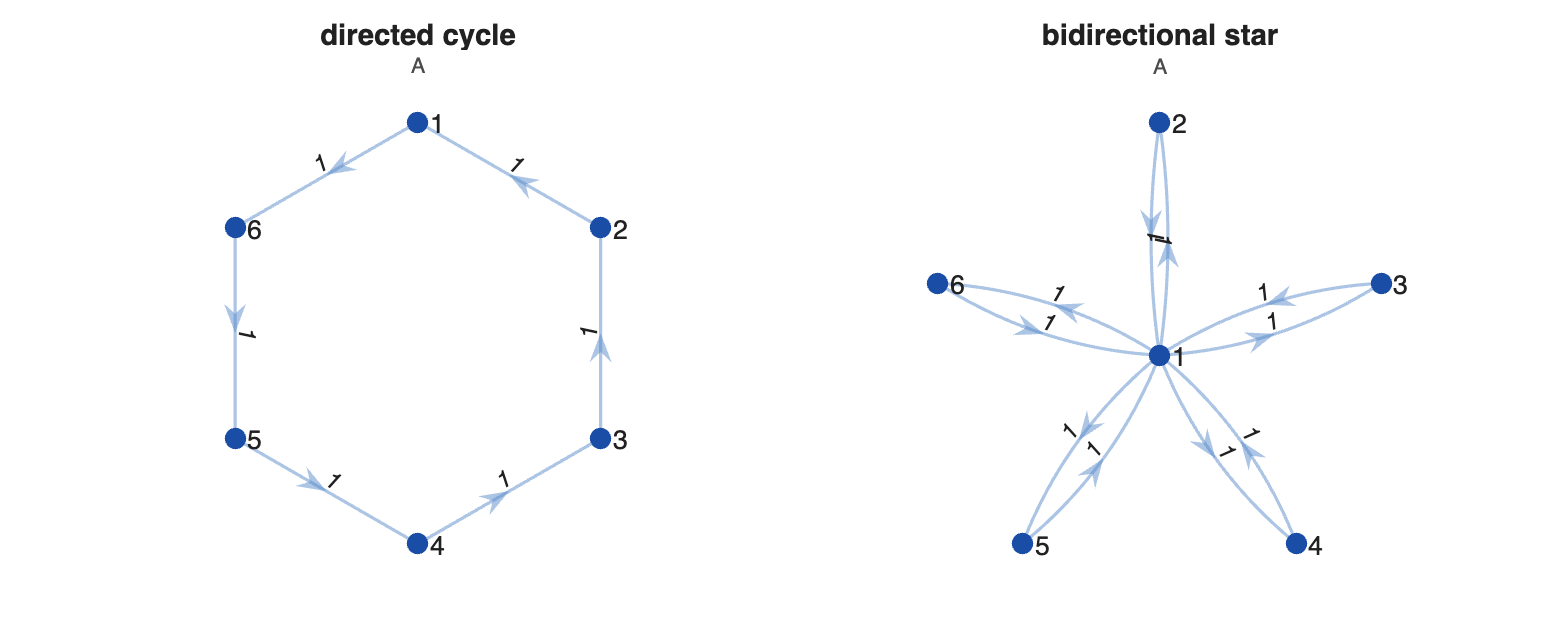

cases = {'directed cycle',     ring_graph(N),                 'circle'; ...
         'bidirectional star', star_graph(N,'bidirectional'), 'star'};

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_graph(cases{k,2}, [], 'Layout', cases{k,3}, ...
        'Title', cases{k,1}, 'Subtitle','A');
end

The three matrices of the model, for the directed cycle: the weights A, the degree matrix D of the row sums, and L = D - A. Every row of L sums to zero, which is why the constant vector is an equilibrium.

A = ring_graph(N)

A =      0     0     0     0     0     1
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0


D = diag(sum(A, 2))

D =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


L = laplacian(A)

L =      1     0     0     0     0    -1
    -1     1     0     0     0     0
     0    -1     1     0     0     0
     0     0    -1     1     0     0
     0     0     0    -1     1     0
     0     0     0     0    -1     1



fprintf('row sums of L: %s\n', mat2str(round(sum(L,2).', 12)));

row sums of L: [0 0 0 0 0 0]



for k = 1:2
    laplacian_report(cases{k,2}, cases{k,1});
    fprintf('\n');
end

directed cycle   (6 agents, continuous time)
  strengths (row sums of A): [1 1 1 1 1 1]
  in-strengths (col sums)  : [1 1 1 1 1 1]   weight-balanced: yes
  strong components : 1   closed: 1
  rooted: yes   ->  converges to CONSENSUS at p'x(0)
  eigenvalue 0 of L: multiplicity 1   spectral gap: 0.5000


bidirectional star   (6 agents, continuous time)
  strengths (row sums of A): [5 1 1 1 1 1]
  in-strengths (col sums)  : [5 1 1 1 1 1]   weight-balanced: yes
  strong components : 1   closed: 1
  rooted: yes   ->  converges to CONSENSUS at p'x(0)
  eigenvalue 0 of L: multiplicity 1   spectral gap: 1.0000


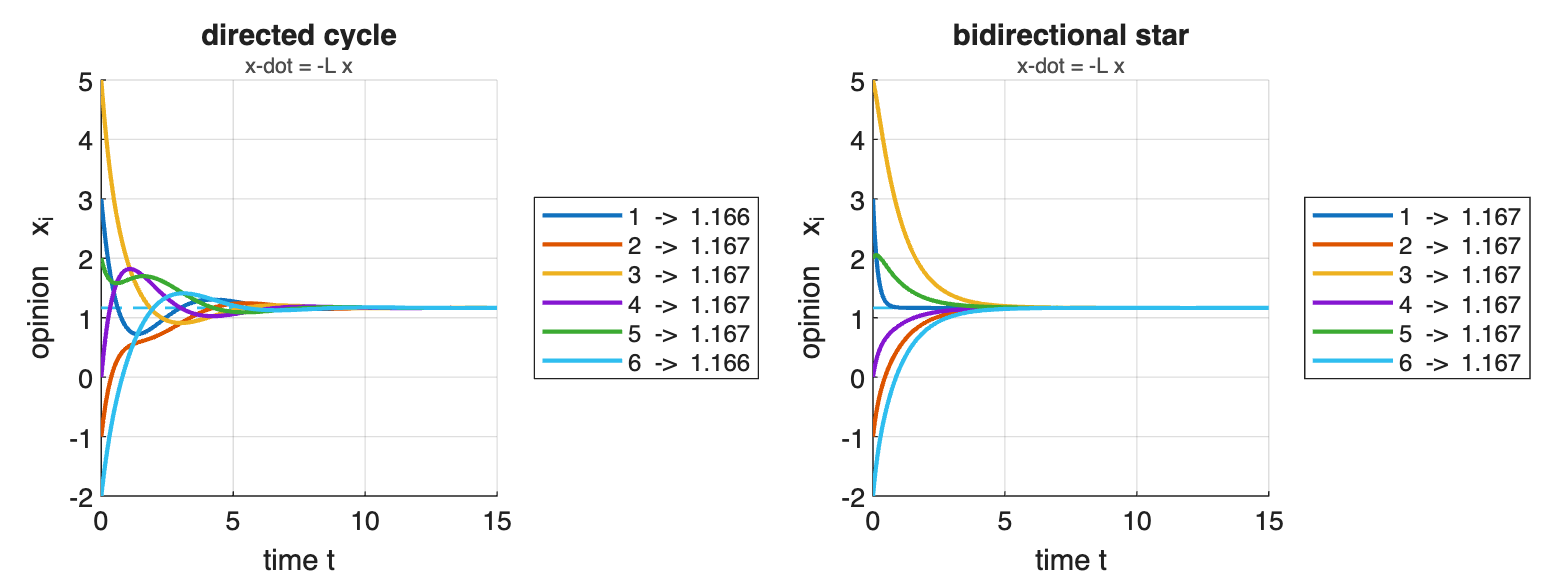

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    p = laplacian_power(cases{k,2});
    X = sim_abelson(cases{k,2}, x0, t);
    nexttile;
    plot_opinions(X, t, 'Limit', (p.' * x0) * ones(N,1), ...
                  'Title', cases{k,1}, 'Subtitle','x-dot = -L x');
end

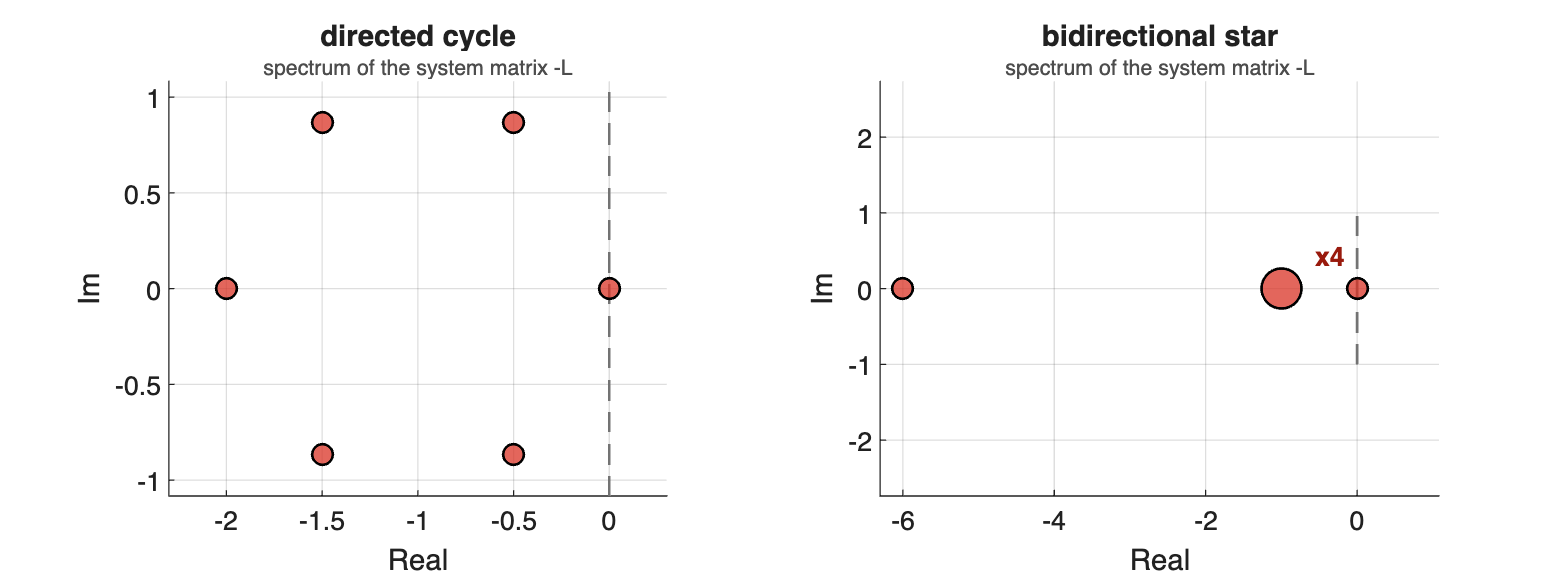

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_eigenvalues(-laplacian(cases{k,2}), 'continuous', ...
        'Title', cases{k,1}, 'Subtitle','spectrum of the system matrix -L');
end


for k = 1:2
    A   = cases{k,2};
    ev  = eig(laplacian(A));
    gap = min(real(ev(abs(ev) > 1e-9)));
    fprintf('%-20s  cycles of length %d   gap = %.4f   x(inf) = %.4f\n', ...
        cases{k,1}, graph_period(A), gap, laplacian_power(A).' * x0);
end

directed cycle        cycles of length 6   gap = 0.5000   x(inf) = 1.1667
bidirectional star    cycles of length 2   gap = 1.0000   x(inf) = 1.1667


One eigenvalue sits at the origin and every other one strictly to its left: the model is Lyapunov stable but not asymptotically stable, and it converges. Both graphs are quasi-strongly connected, so Theorem 2.1 gives consensus, and both are weight-balanced, so the limit is the plain average of the initial opinions.

P = laplacian_limit(ring_graph(N))

P =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667


fprintf('rank(P) = %d,   ||P - 1 p''|| = %.2e,   ||P^2 - P|| = %.2e\n', ...
    rank(P), norm(P - ones(N,1)*laplacian_power(ring_graph(N)).', Inf), norm(P*P - P, Inf));

rank(P) = 1,   ||P - 1 p'|| = 6.66e-16,   ||P^2 - P|| = 8.33e-17


P is the projection onto the null space of L. Its rank is 1, so it is the rank-one matrix 1 p-transpose and every row is the same: whatever the initial condition, all agents end at the same value.

## 2.4.2 Self-loops are invisible to the Laplacian

A self-loop adds equally to the degree and to the weight, so it cancels in L = D - A. The two graphs below therefore generate the same dynamics.

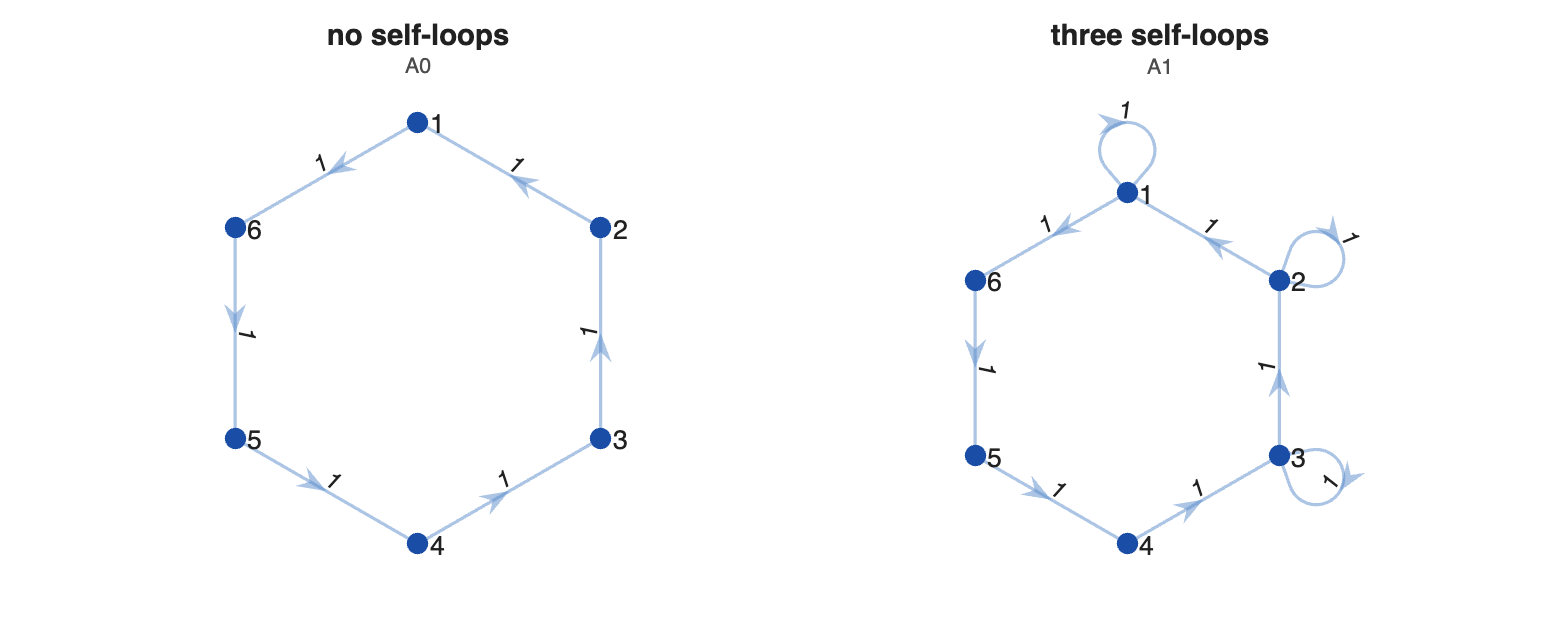

A0 = ring_graph(N);
A1 = ring_graph(N) + diag([1;1;1;0;0;0]);        % self-loops on agents 1, 2, 3

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile; plot_graph(A0, [], 'Title','no self-loops', 'Subtitle','A0');
nexttile; plot_graph(A1, [], 'Title','three self-loops', 'Subtitle','A1');


fprintf('||L(A1) - L(A0)|| = %.3e\n', norm(laplacian(A1) - laplacian(A0), Inf));

||L(A1) - L(A0)|| = 0.000e+00



d = 0;
for m = 0:N
    Am = A0 + diag([ones(m,1); zeros(N-m,1)]);
    d  = max(d, norm(laplacian(Am) - laplacian(A0), Inf));
end
fprintf('max over m = 0 ... %d self-loops : %.3e\n', N, d);

max over m = 0 ... 6 self-loops : 0.000e+00


In a discrete-time averaging model the number of self-loops decides whether the opinions settle at all. Here it changes nothing, which is why no aperiodicity condition appears in Corollary 2.1 or Theorem 2.1.

## 2.4.3 Row sums are free

A is not normalised. Its row sums say how strongly each agent is pulled towards its neighbours, and they may be changed independently of the topology.

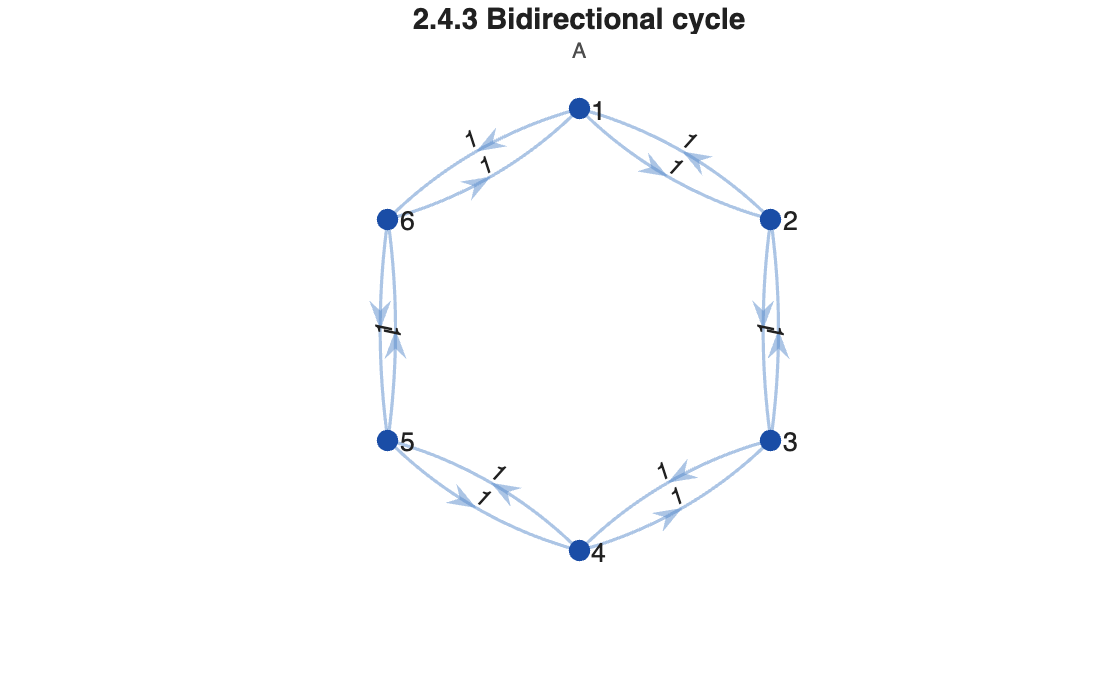

A = ring_graph(N) + ring_graph(N).';        % bidirectional cycle
figure; plot_graph(A, [], 'Title','2.4.3 Bidirectional cycle', 'Subtitle','A')

figure('Position',[0 0 860 450]); hold on
for c = [0.5 1 2]
    X   = sim_abelson(c*A, x0, t);
    ev  = eig(laplacian(c*A));
    gap = min(real(ev(abs(ev) > 1e-9)));
    plot(t, max(X,[],1) - min(X,[],1), 'LineWidth', 1.7, ...
         'DisplayName', sprintf('c = %.1f,  gap = %.2f', c, gap));
    fprintf('c = %.1f : x(inf) = %.4f\n', c, laplacian_power(c*A).' * x0);
end

c = 0.5 : x(inf) = 1.1667
c = 1.0 : x(inf) = 1.1667
c = 2.0 : x(inf) = 1.1667


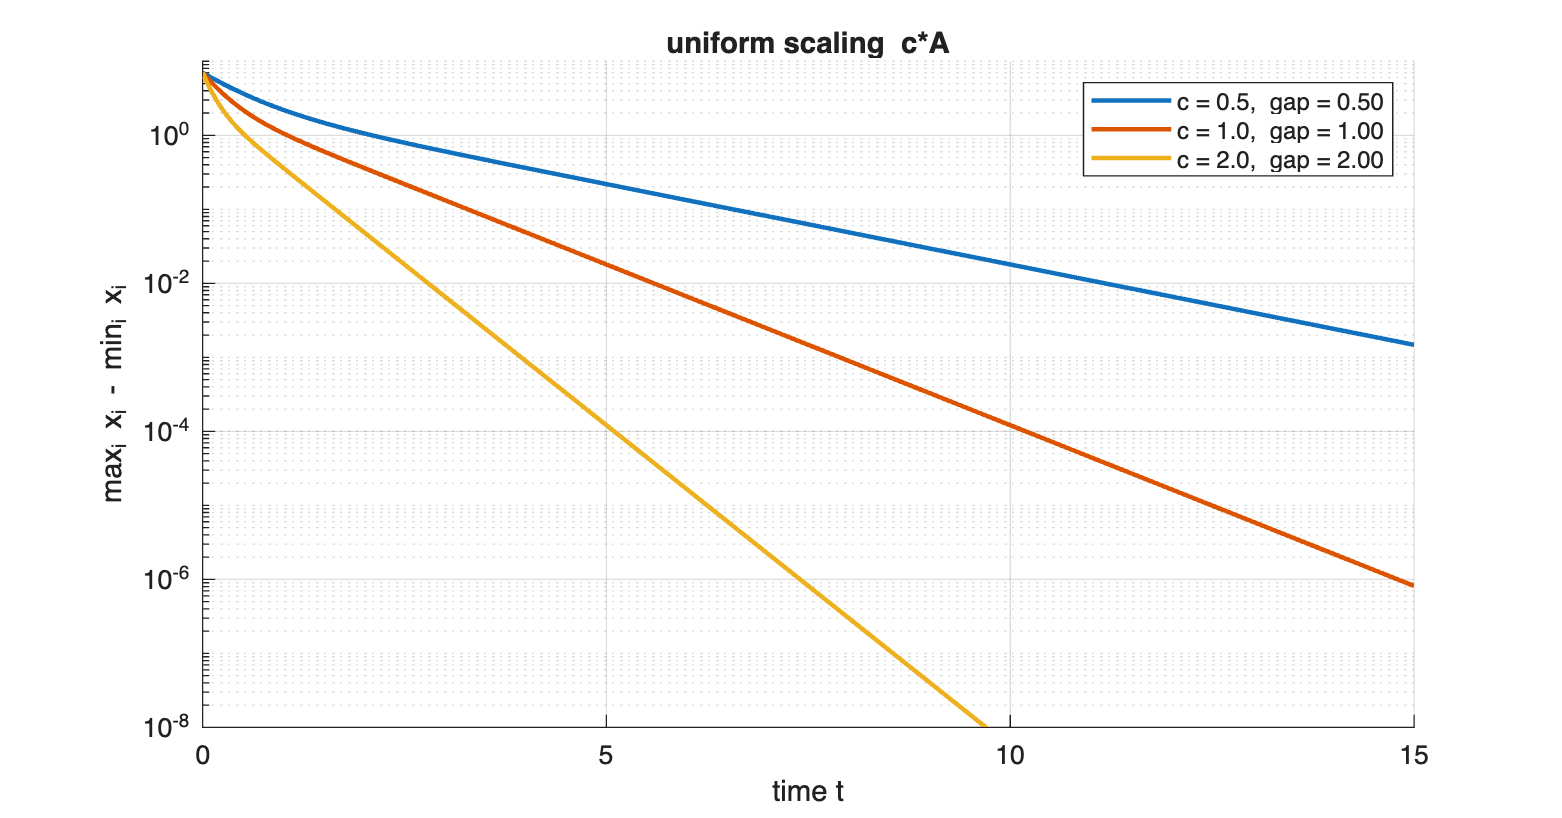

set(gca, 'YScale', 'log'); grid on; legend('Location','northeast');
xlabel('time t'); ylabel('max_i x_i - min_i x_i'); ylim([1e-8 10]);
title('uniform scaling  c*A', 'FontWeight','bold');

Scaling the whole matrix multiplies every eigenvalue of L by c: the dynamics is the same, run at a different speed, and the limit does not move. Scaling a single row is a different matter.

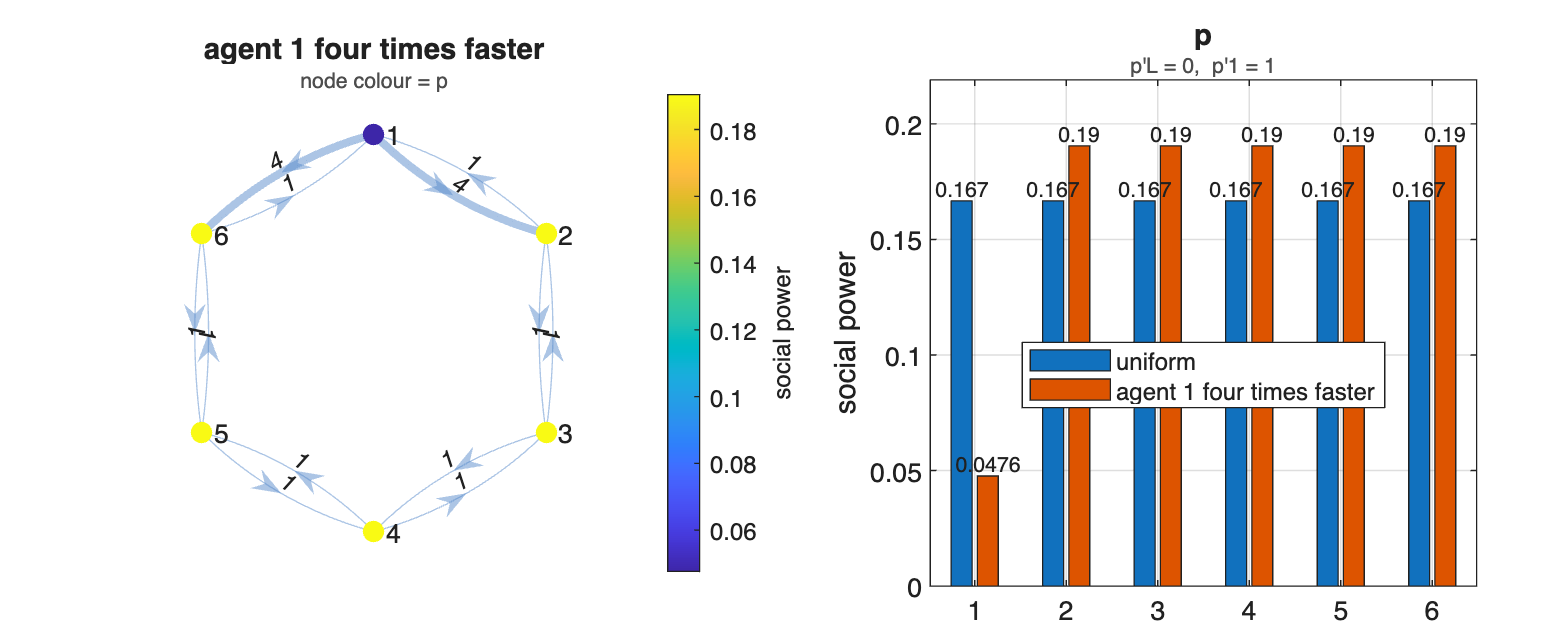

C1 = diag([4 1 1 1 1 1]);                   % agent 1 responds four times faster
Pw = [laplacian_power(A), laplacian_power(C1*A)];

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile; plot_graph(C1*A, [], 'NodeValue', Pw(:,2), 'NodeName','social power', ...
    'Title','agent 1 four times faster', 'Subtitle','node colour = p');
nexttile; plot_bars(Pw, [], 'Series', {'uniform','agent 1 four times faster'}, ...
    'YLabel','social power', 'Title','p', 'Subtitle','p''L = 0,  p''1 = 1');


fprintf('uniform        : p1 = %.4f,  x(inf) = %.4f\n', Pw(1,1), Pw(:,1).'*x0);

uniform        : p1 = 0.1667,  x(inf) = 1.1667


fprintf('agent 1 faster : p1 = %.4f,  x(inf) = %.4f\n', Pw(1,2), Pw(:,2).'*x0);

agent 1 faster : p1 = 0.0476,  x(inf) = 0.9048


Scaling row i by c replaces p by a vector proportional to C^{-1} p. The agent that reacts fastest to its neighbours therefore ends up with the smallest weight in the outcome. Neither effect is expressible in a model whose rows are forced to sum to one.

## 2.4.4 The asymptotic vector p as social power

Theorem 2.1 gives the limit as x(inf) = (px(0)) 1, so p decides how much each agents initial opinion counts in the outcome. It is a centrality measure generated by the dynamics rather than postulated on the graph. The three rooted topologies below have very different profiles.

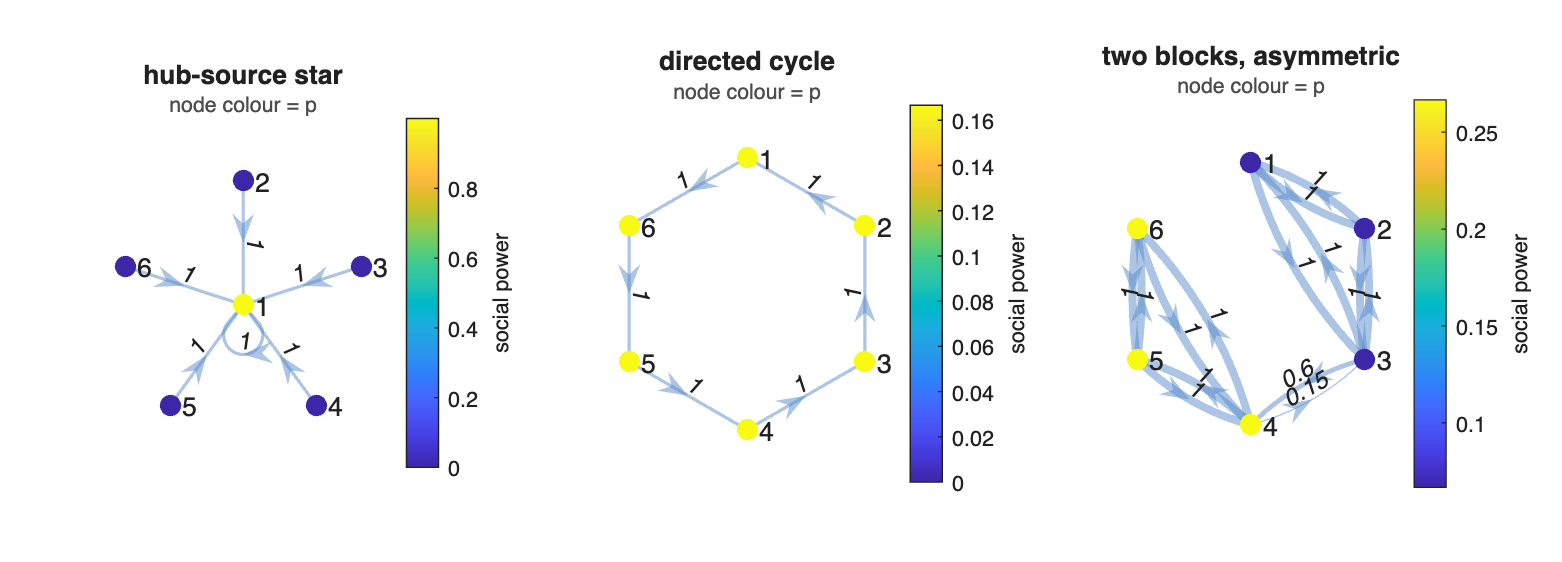

% two triangles whose bridge is much stronger in one direction than the other
Ab = two_communities(N/2, N/2, 0.15);
Ab(3,4) = 0.6;                       % block 1 listens hard to block 2
Ab(4,3) = 0.15;                      % block 2 barely listens back

powers = {'hub-source star',        star_graph(N),  'star'; ...
          'directed cycle',         ring_graph(N),  'circle'; ...
          'two blocks, asymmetric', Ab,             'circle'};

Pp = zeros(N, 3);
for k = 1:3, Pp(:,k) = laplacian_power(powers{k,2}); end

figure('Position',[0 0 1250 450]);
tiledlayout(1, 3, 'TileSpacing','compact', 'Padding','compact');
for k = 1:3
    nexttile;
    plot_graph(powers{k,2}, [], 'Layout', powers{k,3}, 'NodeValue', Pp(:,k), ...
        'NodeName','social power', 'Title', powers{k,1}, 'Subtitle','node colour = p');
end

The third graph in numbers, and the three power vectors side by side.

Ab

Ab =          0    1.0000    1.0000         0         0         0
    1.0000         0    1.0000         0         0         0
    1.0000    1.0000         0    0.6000         0         0
         0         0    0.1500         0    1.0000    1.0000
         0         0         0    1.0000         0    1.0000
         0         0         0    1.0000    1.0000         0


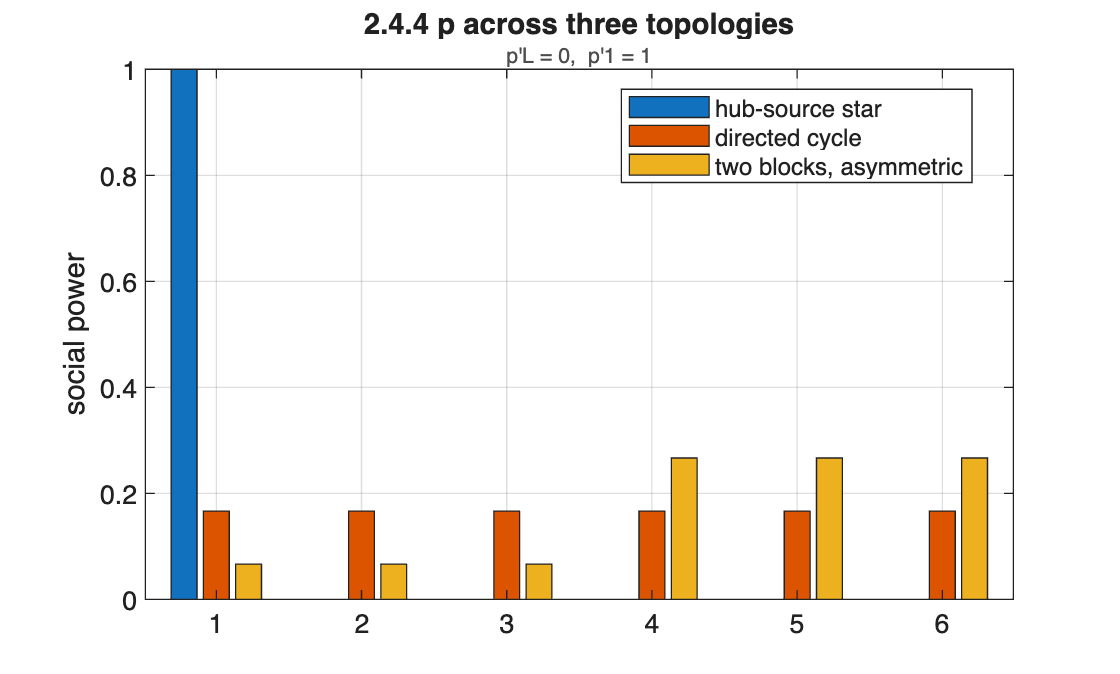


figure;
plot_bars(Pp, [], 'Series', powers(:,1).', 'YLabel','social power', ...
    'Title','2.4.4 p across three topologies', 'Subtitle','p''L = 0,  p''1 = 1')


for k = 1:3
    fprintf('%-24s p = %-42s  x(inf) = %+.4f\n', powers{k,1}, ...
        mat2str(round(Pp(:,k).',4)), Pp(:,k).' * x0);
end

hub-source star          p = [1 0 0 0 0 0]                               x(inf) = +3.0000
directed cycle           p = [0.1667 0.1667 0.1667 0.1667 0.1667 0.1667]  x(inf) = +1.1667
two blocks, asymmetric   p = [0.0667 0.0667 0.0667 0.2667 0.2667 0.2667]  x(inf) = +0.4667


The hub of the source star is the only agent nobody influences, so it carries the whole weight and the group ends at its opinion. The directed cycle is balanced, so power is shared equally. In the two-block graph the side the bridge favours ends up four times as influential as the other, even though the two blocks are identical.

Social power is not the same as being listened to. The in-strengths below do not reproduce p.

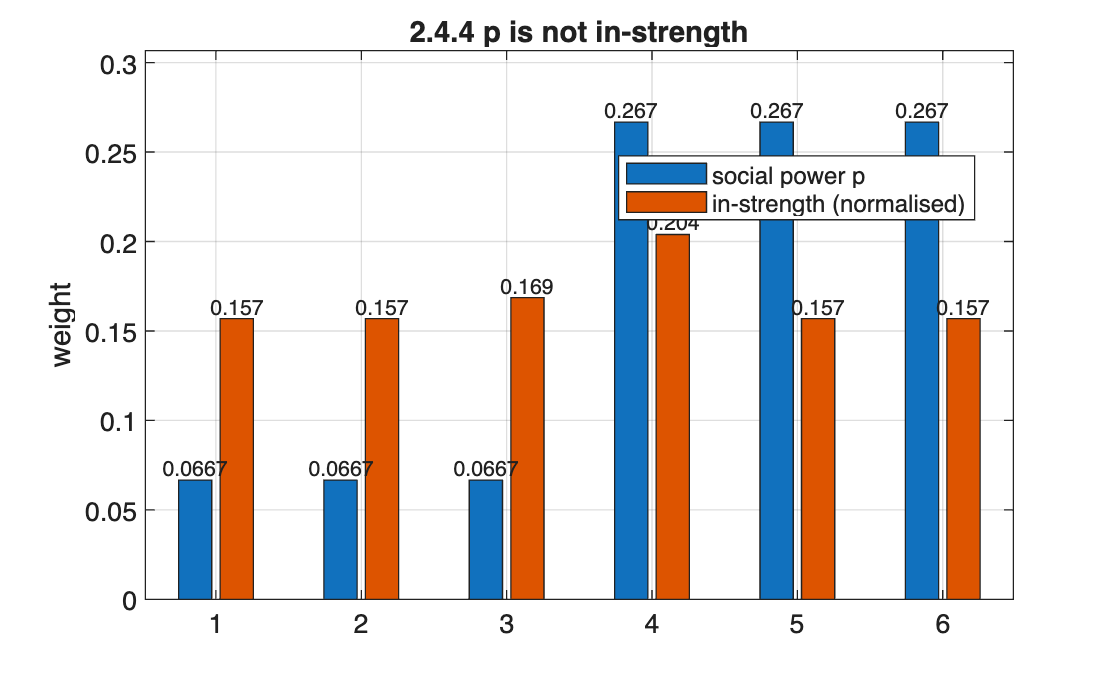

A  = Ab;
p  = laplacian_power(A);
ins = sum(A,1).';  ins = ins / sum(ins);

figure;
plot_bars([p, ins], [], 'Series', {'social power p','in-strength (normalised)'}, ...
    'YLabel','weight', 'Title','2.4.4 p is not in-strength', 'Subtitle','')


fprintf('most listened-to agent : %d\n', find(ins == max(ins), 1));

most listened-to agent : 4


fprintf('most influential agent : %d\n', find(p   == max(p),   1));

most influential agent : 6


Two properties make p meaningful rather than merely defined. It is conserved along the flow, so px(t) is fixed from the start, and it is exactly the row of the limit operator.

X = sim_abelson(A, x0, t);
fprintf('max |p''x(t) - p''x(0)| over the run : %.2e\n', max(abs(p.'*X - p.'*x0)));

max |p'x(t) - p'x(0)| over the run : 3.22e-15



P = laplacian_limit(A);
fprintf('||P - 1 p''||                        : %.2e\n', norm(P - ones(N,1)*p.', Inf));

||P - 1 p'||                        : 3.61e-16


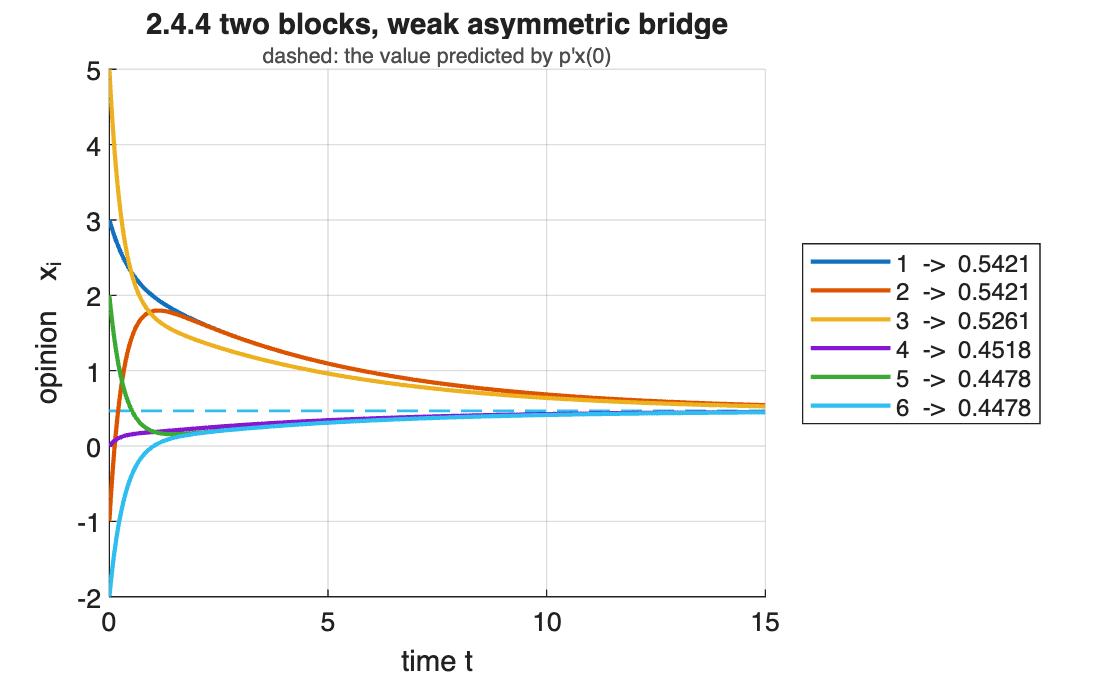


figure;
plot_opinions(X, t, 'Limit', (p.'*x0)*ones(N,1), ...
    'Title','2.4.4 two blocks, weak asymmetric bridge', ...
    'Subtitle','dashed: the value predicted by p''x(0)')

When A happens to be row-stochastic, L = I - A and pL = 0 becomes pA = p, so p is exactly the social power of the discrete-time model on the same weights. The two notions coincide, and the continuous-time one is the more general of the two because A need not be normalised.

W = [1/2 1/2 0; 1/3 1/3 1/3; 0 1/2 1/2];      % row-stochastic
fprintf('L = I - W ?                 %.2e\n', norm(laplacian(W) - (eye(3) - W), Inf));

L = I - W ?                 0.00e+00


fprintf('discrete-time social power: %s\n', mat2str(round(social_power(W).', 6)));

discrete-time social power: [0.285714 0.428571 0.285714]


fprintf('laplacian_power           : %s\n', mat2str(round(laplacian_power(W).', 6)));

laplacian_power           : [0.285714 0.428571 0.285714]


## 2.4.5 Rootedness is the only condition

Theorem 2.1 asks for one thing: a quasi-strongly connected graph. When that fails the model still converges, but to several values. A row of A that is entirely zero makes x-dot_i = 0, which is the stubborn agent of section 2.3.

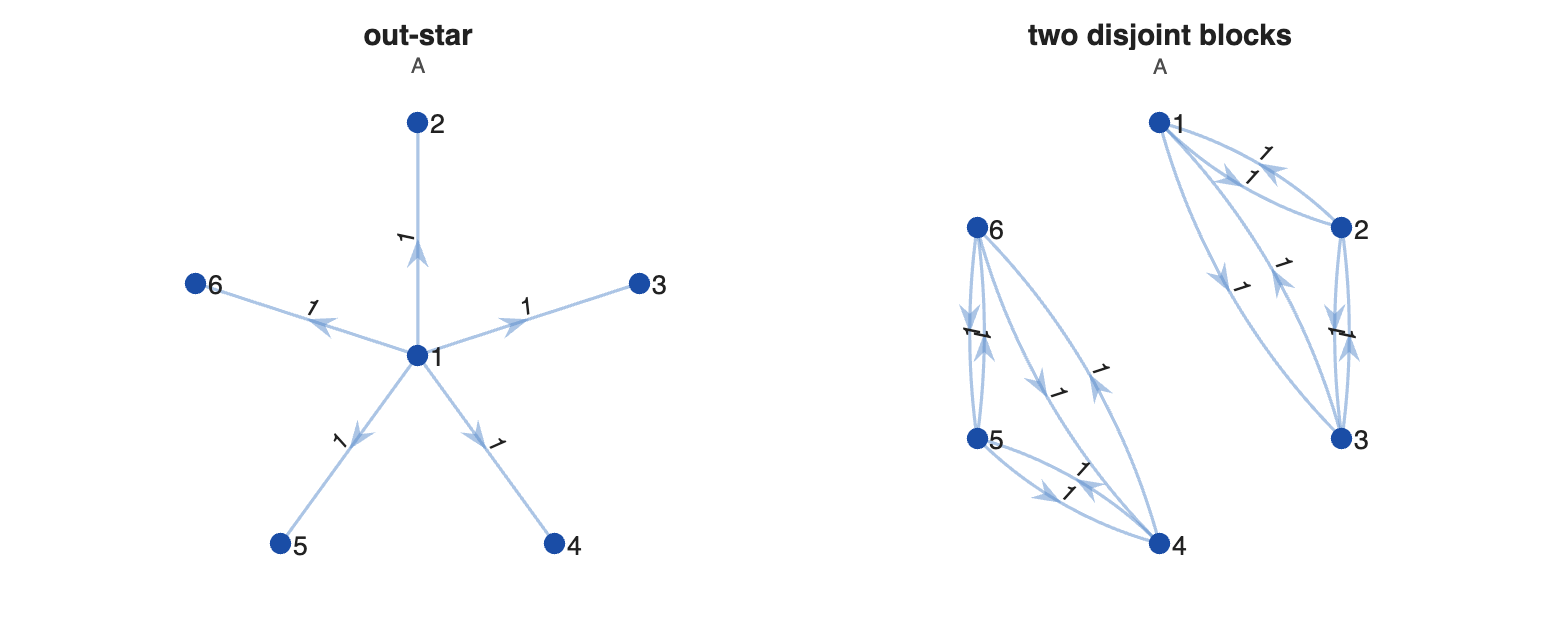

cases = {'out-star',            common_topology('star-out'),   'star'; ...
         'two disjoint blocks', two_communities(N/2, N/2, 0),  'circle'};

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_graph(cases{k,2}, [], 'Layout', cases{k,3}, ...
        'Title', cases{k,1}, 'Subtitle','A');
end


for k = 1:2
    laplacian_report(cases{k,2}, cases{k,1});
    fprintf('\n');
end

out-star   (6 agents, continuous time)
  strengths (row sums of A): [5 0 0 0 0 0]
  in-strengths (col sums)  : [0 1 1 1 1 1]   weight-balanced: no
  strong components : 6   closed: 5
  rooted: no    ->  converges, but NOT to consensus (one limit per closed component)
  eigenvalue 0 of L: multiplicity 5   spectral gap: 5.0000
  stubborn agents (zero rows of A): [2 3 4 5 6]


two disjoint blocks   (6 agents, continuous time)
  strengths (row sums of A): [2 2 2 2 2 2]
  in-strengths (col sums)  : [2 2 2 2 2 2]   weight-balanced: yes
  strong components : 2   closed: 2
  rooted: no    ->  converges, but NOT to consensus (one limit per closed component)
  eigenvalue 0 of L: multiplicity 2   spectral gap: 3.0000


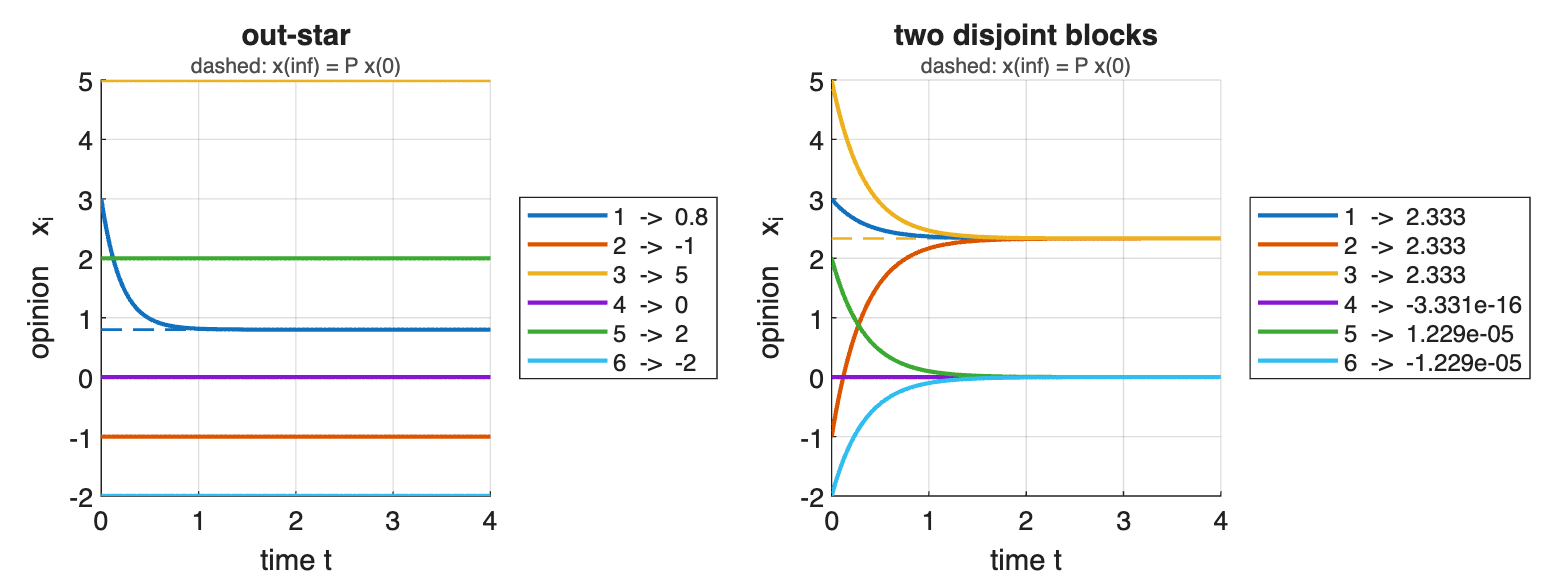

ts = linspace(0, 4, 300);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    X = sim_abelson(cases{k,2}, x0, ts);
    plot_opinions(X, ts, 'Limit', laplacian_limit(cases{k,2}) * x0, ...
        'Title', cases{k,1}, 'Subtitle','dashed: x(inf) = P x(0)');
end

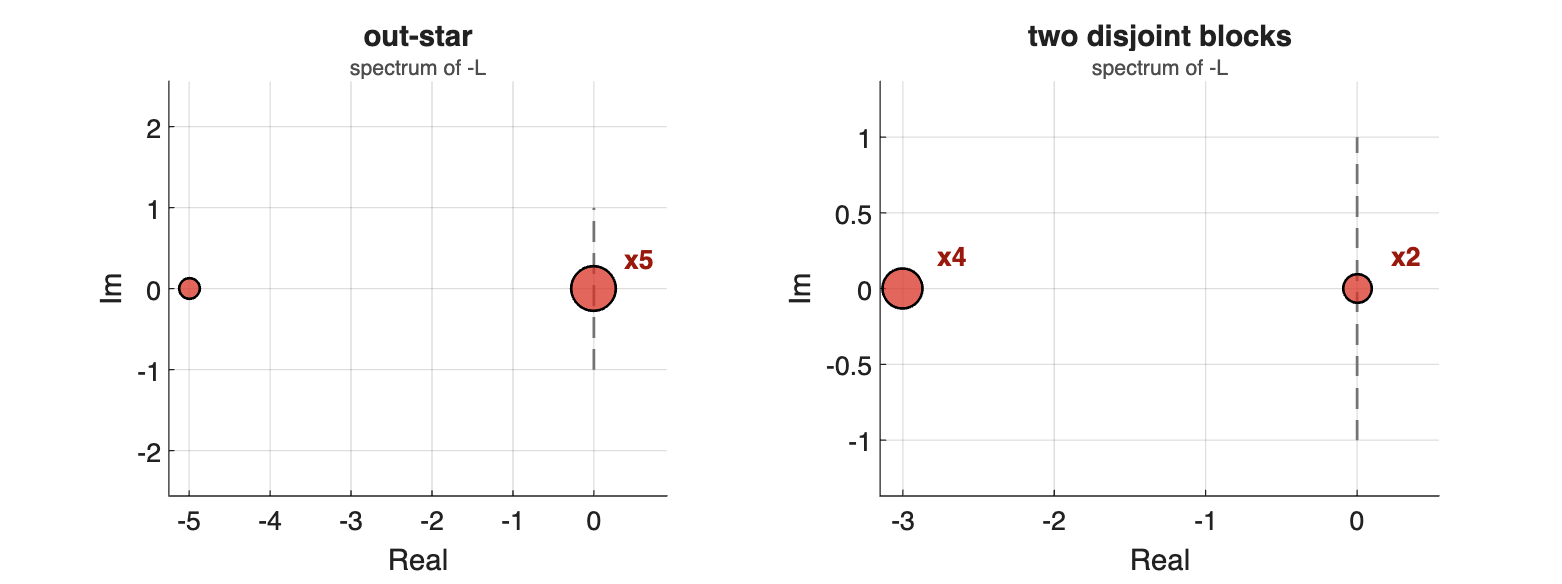


figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_eigenvalues(-laplacian(cases{k,2}), 'continuous', ...
        'Title', cases{k,1}, 'Subtitle','spectrum of -L');
end


for k = 1:2
    fprintf('%-22s rank(P) = %d   closed components = %d\n', cases{k,1}, ...
        rank(laplacian_limit(cases{k,2})), numel(graph_summary(cases{k,2}).closed));
end

out-star               rank(P) = 5   closed components = 5
two disjoint blocks    rank(P) = 2   closed components = 2


Both converge and neither reaches consensus. The rank of P, the multiplicity of the eigenvalue 0 of L and the number of closed strong components are the same number in each case: 5 for the out-star, whose five leaves never move, and 2 for the disjoint blocks.

## 2.4.6 The spectral gap sets the rate

All the eigenvalues of -L other than 0 have negative real part, and the one closest to the imaginary axis governs how fast the flow settles. That distance is the spectral gap: min Re(lambda) over the nonzero eigenvalues of L, the Fiedler value when the graph is undirected.

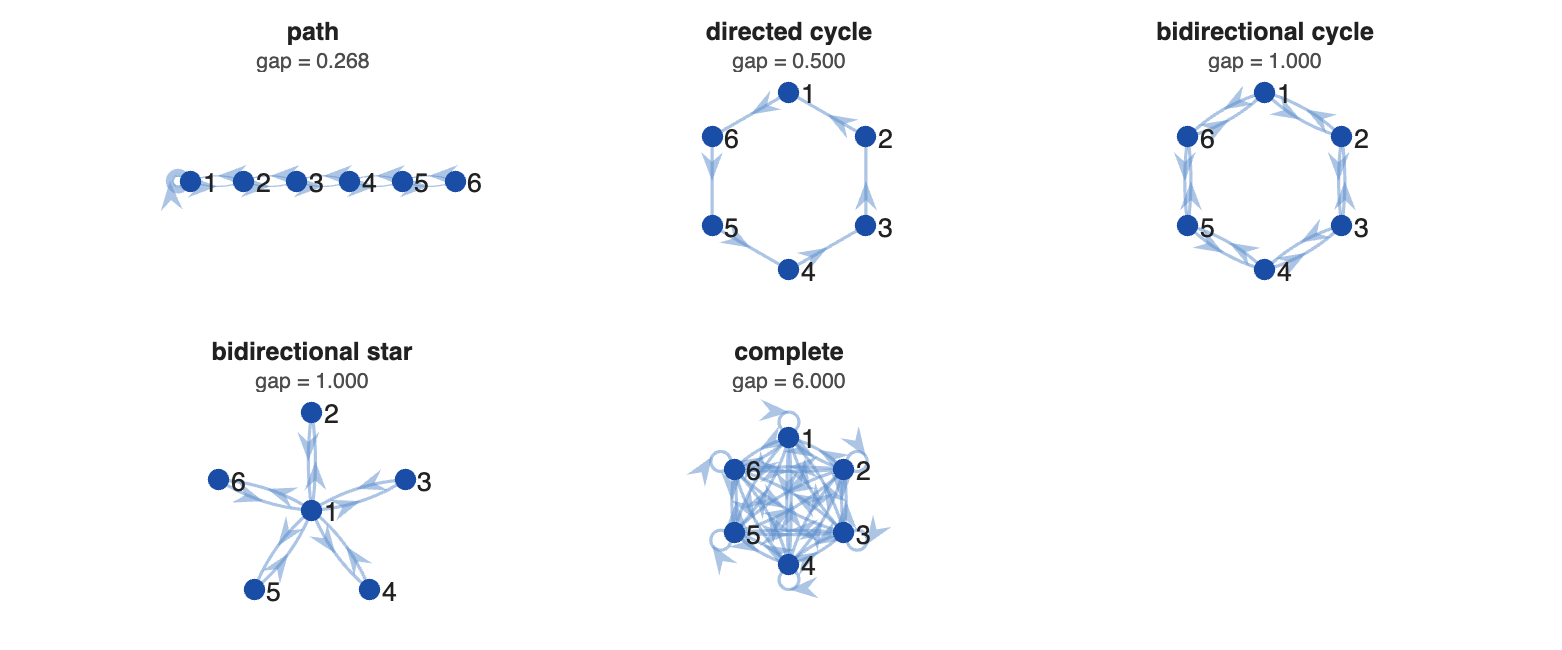

tops = {'path',                path_graph(N) + path_graph(N).',   'line'; ...
        'directed cycle',      ring_graph(N),                     'circle'; ...
        'bidirectional cycle', ring_graph(N) + ring_graph(N).',   'circle'; ...
        'bidirectional star',  star_graph(N,'bidirectional'),     'star'; ...
        'complete',            complete_graph(N),                 'circle'};

figure('Position',[0 0 1250 520]);
tiledlayout(2, 3, 'TileSpacing','compact', 'Padding','compact');
for k = 1:size(tops,1)
    nexttile;
    ev  = eig(laplacian(tops{k,2}));
    gap = min(real(ev(abs(ev) > 1e-9)));
    plot_graph(tops{k,2}, [], 'Layout', tops{k,3}, 'Weights', false, ...
        'Title', tops{k,1}, 'Subtitle', sprintf('gap = %.3f', gap));
end

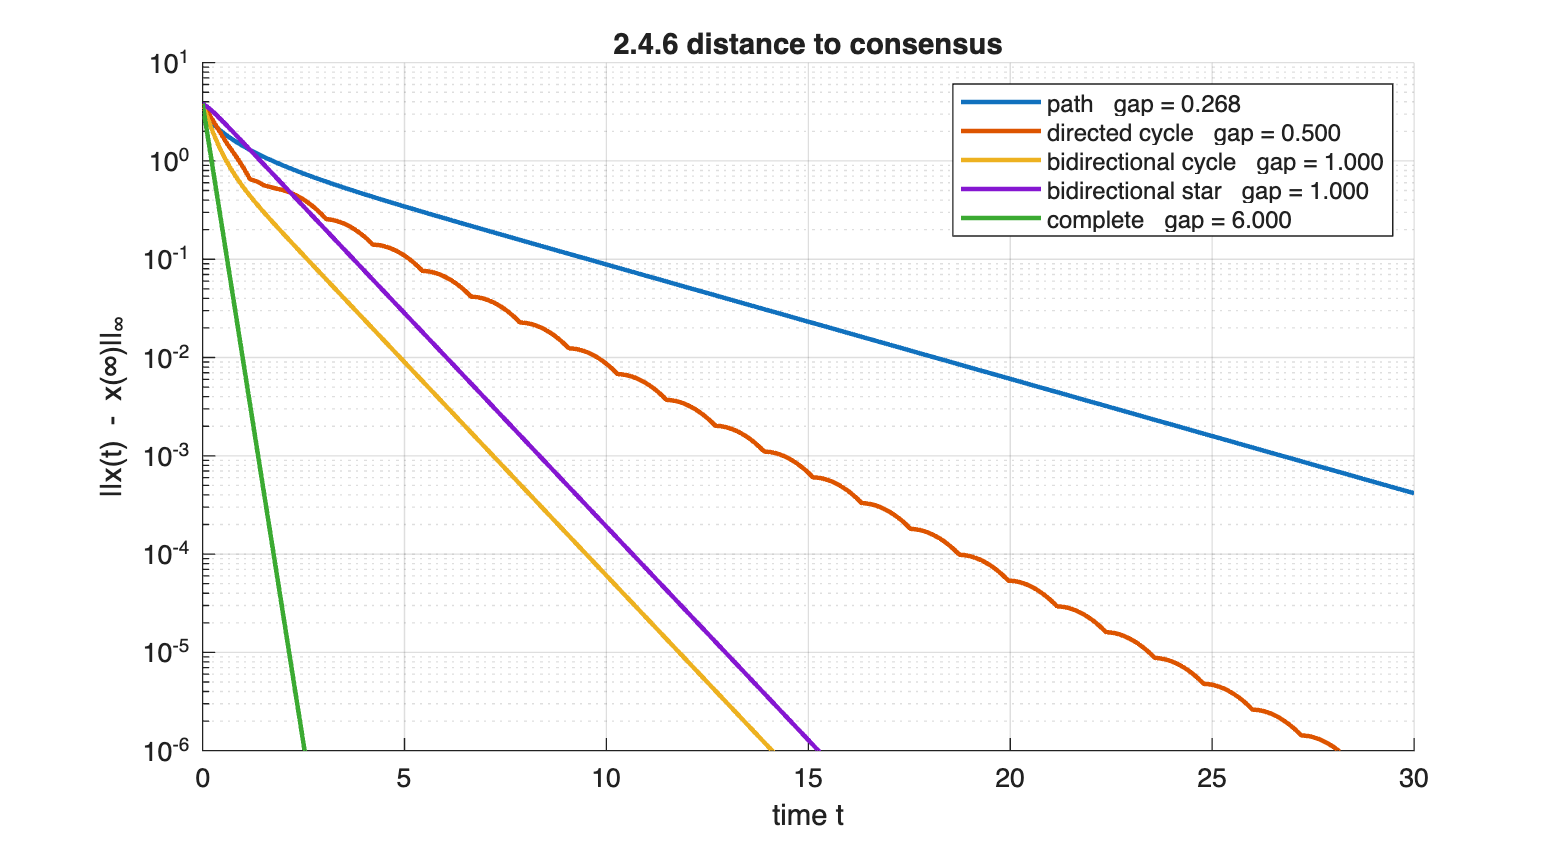

tg   = linspace(0, 30, 900);
rows = cell(size(tops,1), 1);

figure('Position',[0 0 870 470]); hold on
for k = 1:size(tops,1)
    A    = tops{k,2};
    ev   = eig(laplacian(A));
    gap  = min(real(ev(abs(ev) > 1e-9)));
    X    = sim_abelson(A, x0, tg);
    dev  = max(abs(X - laplacian_power(A).' * x0), [], 1);
    plot(tg, dev, 'LineWidth', 1.7, ...
         'DisplayName', sprintf('%s   gap = %.3f', tops{k,1}, gap));
    j = find(dev < 1e-3, 1);
    rows{k} = {tops{k,1}, gap, tg(j), gap*tg(j)};
end
set(gca, 'YScale', 'log'); grid on; legend('Location','northeast');
xlabel('time t'); ylabel('||x(t) - x(\infty)||_\infty'); ylim([1e-6 10]);
title('2.4.6 distance to consensus', 'FontWeight','bold');


rate = cell2table(vertcat(rows{:}), ...
    'VariableNames', {'topology','gap','t_settle','gap_times_t'})

rate = 5×4 table
           topology              gap      t_settle    gap_times_t
    _______________________    _______    ________    ___________

    {'path'               }    0.26795      26.73       7.1622   
    {'directed cycle'     }        0.5     14.383       7.1913   
    {'bidirectional cycle'}          1      7.208        7.208   
    {'bidirectional star' }          1      8.376        8.376   
    {'complete'           }          6     1.4016       8.4093   


The last column is nearly constant over a twenty-fold range of gaps: the settling time is essentially the reciprocal of the gap. Denser connectivity means a larger gap and a faster approach to consensus.

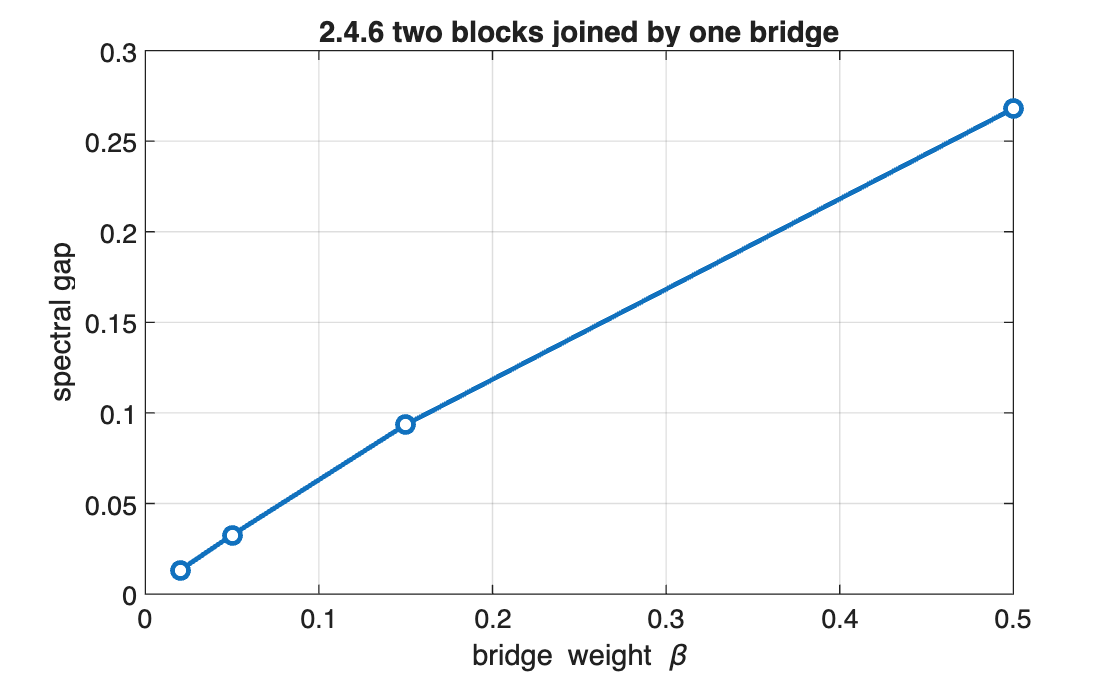

beta = [0.02 0.05 0.15 0.5];
gapb = zeros(size(beta));
for k = 1:numel(beta)
    ev = eig(laplacian(two_communities(N/2, N/2, beta(k))));
    gapb(k) = min(real(ev(abs(ev) > 1e-9)));
end

figure;
plot(beta, gapb, 'o-', 'LineWidth', 1.8, 'MarkerFaceColor','w'); grid on
xlabel('bridge weight \beta'); ylabel('spectral gap');
title('2.4.6 two blocks joined by one bridge', 'FontWeight','bold');

A weak bridge makes the gap small. The group still reaches consensus, but only after a long phase in which the two blocks have agreed internally and barely with each other.

## 2.4.7 Sampling and discretisation

Two different statements connect this chapter to the discrete-time model, and they are worth keeping apart.

Lemma 2.1 is exact. For any tau > 0 the matrix exp(-tau L) is stochastic with positive diagonal entries, so the sampled sequence x(k tau) obeys a discrete-time averaging model exactly, at every tau. Nothing is approximated and nothing improves as tau shrinks.

The discretisation statement is a limit. Replacing exp(-tau L) by its first-order expansion I - tau L gives a different, approximate discrete model, which is stochastic only while tau <= 1 / max_i d_i and whose trajectory approaches the flow as tau tends to zero.

A   = ring_graph(N) + ring_graph(N).';
L   = laplacian(A);
tau = 0.4;
W   = expm(-L * tau);

fprintf('exp(-tau L): row-stochastic = %d,  min diagonal = %.4f,  min entry = %.3e\n', ...
    is_row_stochastic(W), min(diag(W)), min(W(:)));

exp(-tau L): row-stochastic = 1,  min diagonal = 0.5242,  min entry = 9.975e-03


fprintf('Euler bound: tau <= 1 / max_i d_i = %.4f\n', 1/max(sum(A,2)));

Euler bound: tau <= 1 / max_i d_i = 0.5000


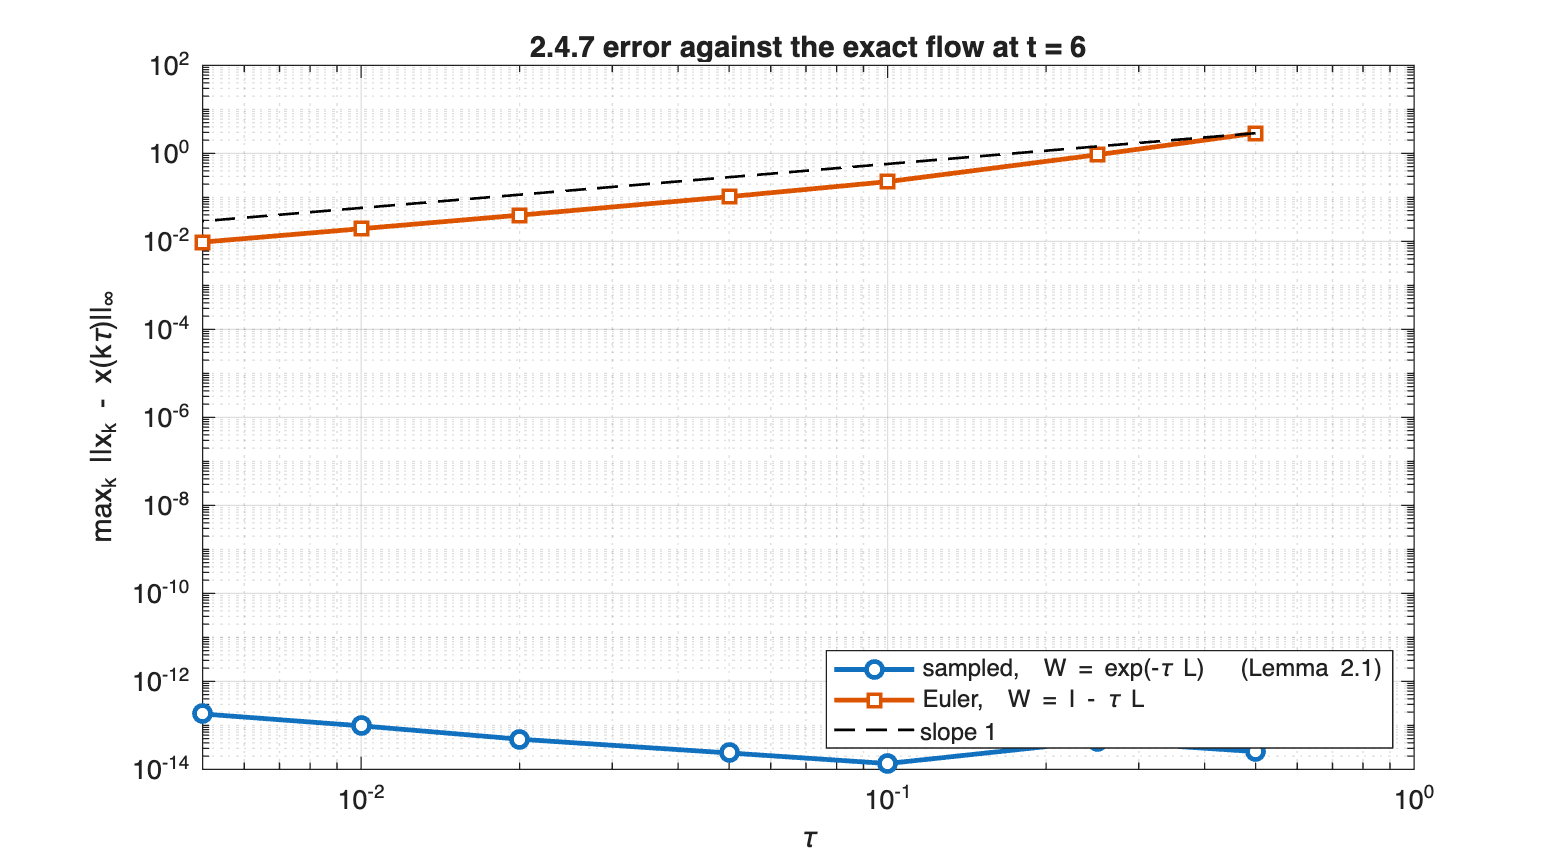

Tend = 6;
taus = [0.5 0.25 0.1 0.05 0.02 0.01 0.005];
errExact = zeros(size(taus));
errEuler = zeros(size(taus));

for j = 1:numel(taus)
    tau = taus(j);  K = round(Tend/tau);
    Xc = sim_abelson(A, x0, tau*(0:K));
    Xs = sim_degroot(expm(-L*tau), x0, K);          % Lemma 2.1: exact
    Xe = zeros(N, K+1);  Xe(:,1) = x0;              % Euler: approximate
    for m = 1:K, Xe(:,m+1) = (eye(N) - tau*L) * Xe(:,m); end
    errExact(j) = max(abs(Xs(:) - Xc(:)));
    errEuler(j) = max(abs(Xe(:) - Xc(:)));
end

figure('Position',[0 0 850 470]);
loglog(taus, max(errExact,1e-16), 'o-', 'LineWidth',1.8, 'MarkerFaceColor','w', ...
       'DisplayName','sampled,  W = exp(-\tau L)   (Lemma 2.1)'); hold on
loglog(taus, errEuler, 's-', 'LineWidth',1.8, 'MarkerFaceColor','w', ...
       'DisplayName','Euler,  W = I - \tau L');
loglog(taus, taus*errEuler(1)/taus(1), 'k--', 'LineWidth',1, 'DisplayName','slope 1');
grid on; legend('Location','southeast');
xlabel('\tau'); ylabel('max_k ||x_k - x(k\tau)||_\infty');
title('2.4.7 error against the exact flow at t = 6', 'FontWeight','bold');


disp(table(taus.', errExact.', errEuler.', ...
     'VariableNames', {'tau','sampled_exact','euler'}))

     tau     sampled_exact      euler  
    _____    _____________    _________

      0.5     2.5313e-14          2.871
     0.25     4.3743e-14        0.92612
      0.1     1.3545e-14        0.22693
     0.05     2.3537e-14        0.10335
     0.02     4.8406e-14       0.039323
     0.01     9.7478e-14        0.01936
    0.005     1.8141e-13      0.0096065



The sampled model sits at rounding error for every tau, including tau = 0.5: that is the content of Lemma 2.1. The Euler model has an error proportional to tau, and only in the limit does it reproduce the flow. The two agree to first order because exp(-tau L) = I - tau L + O(tau^2).

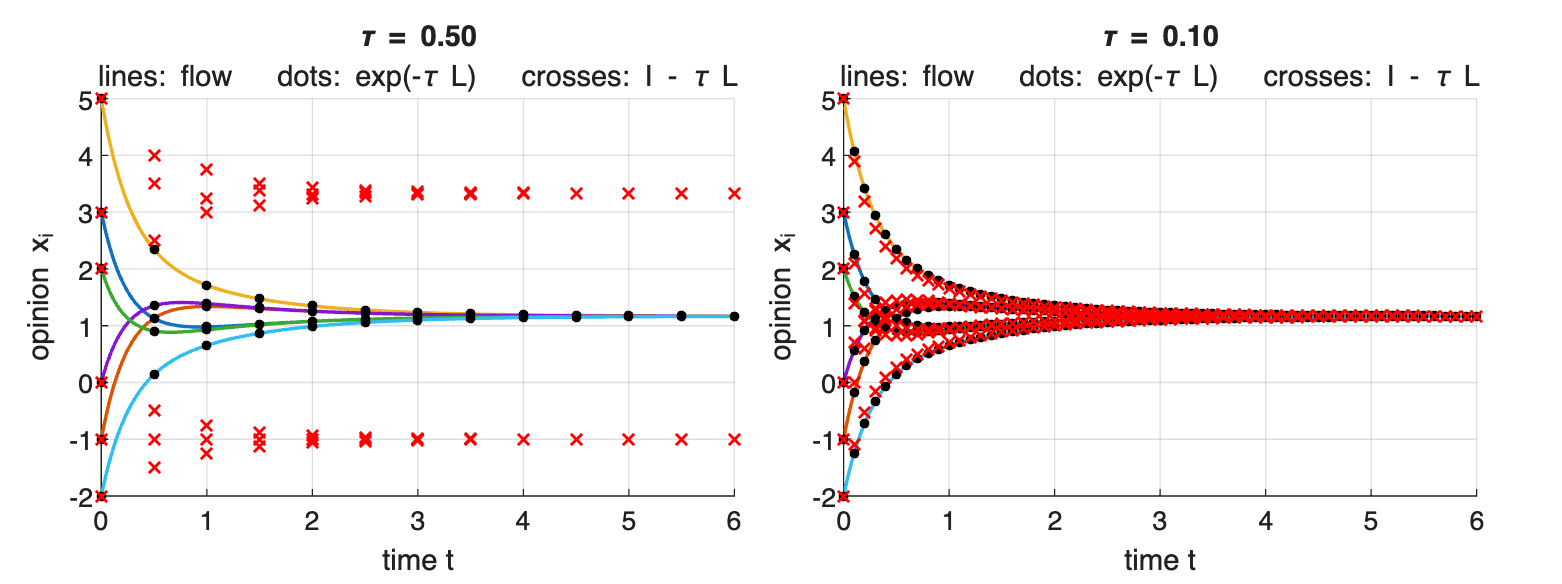

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for tau = [0.5 0.1]
    K  = round(6/tau);
    Xc = sim_abelson(A, x0, linspace(0, 6, 400));
    Xs = sim_degroot(expm(-L*tau), x0, K);
    Xe = zeros(N, K+1); Xe(:,1) = x0;
    for m = 1:K, Xe(:,m+1) = (eye(N) - tau*L) * Xe(:,m); end

    nexttile; hold on
    plot(linspace(0,6,400), Xc.', 'LineWidth', 1.3);
    plot(tau*(0:K), Xs.', 'k.',  'MarkerSize', 11);
    plot(tau*(0:K), Xe.', 'rx',  'MarkerSize', 6, 'LineWidth', 1);
    grid on; xlabel('time t'); ylabel('opinion x_i');
    title(sprintf('\\tau = %.2f', tau), 'FontWeight','bold');
    subtitle('lines: flow   dots: exp(-\tau L)   crosses: I - \tau L');
end

At tau = 0.5 the dots of the sampled model lie on the curves while the crosses of the Euler model are visibly off them; at tau = 0.1 both follow the flow. This is the sense in which the continuous-time model is the limit of a discrete-time averaging model as the interval between updates becomes small.